See figure, taken from Wiley: Incompressible Flow (4th Ed.)

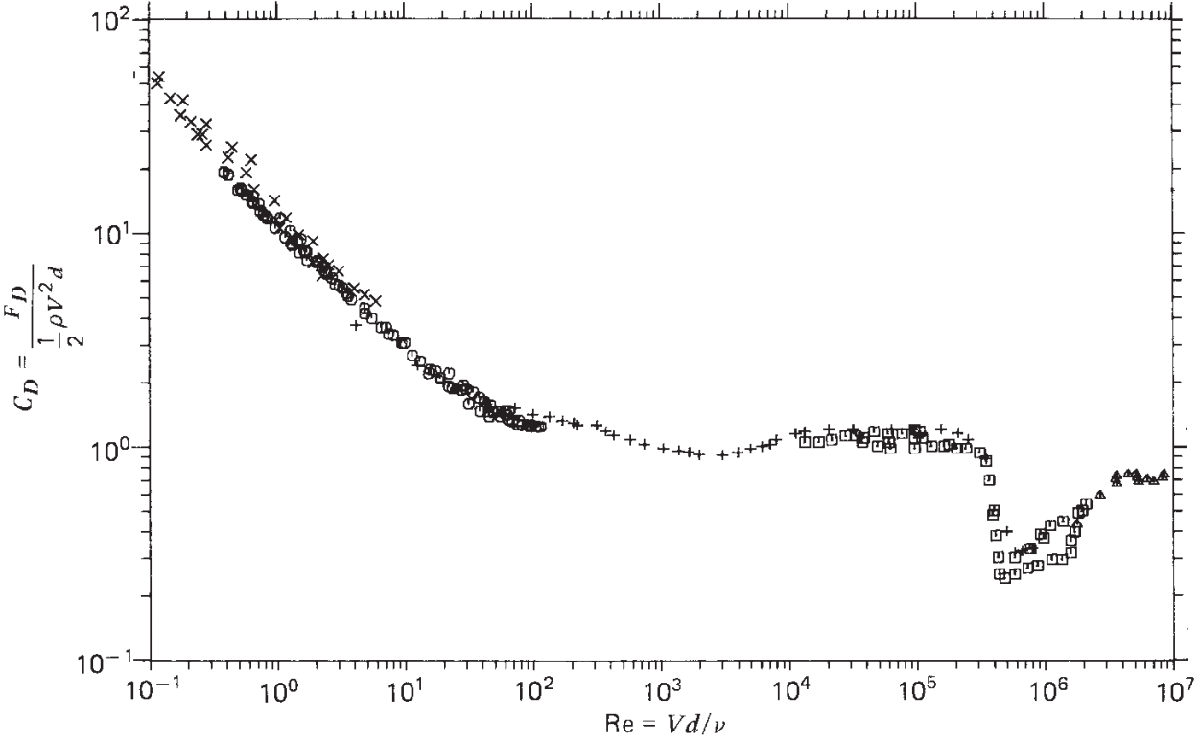

This data was digitized with Engauge Digitizer.

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "Data"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Figfromincompressibleflowwiley = readtable("Fig_from_incompressible_flow_wiley.csv", opts);

%% Clear temporary variables
clear opts

Now, we analyze.

log10_Re = table2array(Figfromincompressibleflowwiley(:,"x"));
log10_Cd = table2array(Figfromincompressibleflowwiley(:,"Data"));
loglog(10.^log10_Re, 10.^log10_Cd,".")
grid on
xlabel("Re")
ylabel("Cd")
title("Raw Data")
drawnow

Isolate the subcritical data:

log10_Re_subcrit = log10_Re(10.^log10_Re < 200000);
log10_Cd_subcrit = log10_Cd(10.^log10_Re < 200000);

Also isolate supercritical data:

log10_Re_supercrit = log10_Re(10.^log10_Re > 600000);
log10_Cd_supercrit = log10_Cd(10.^log10_Re > 600000);

And fit it:

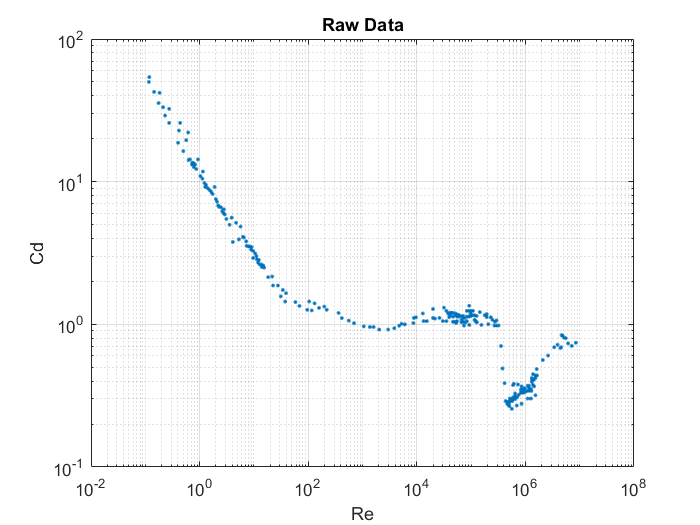

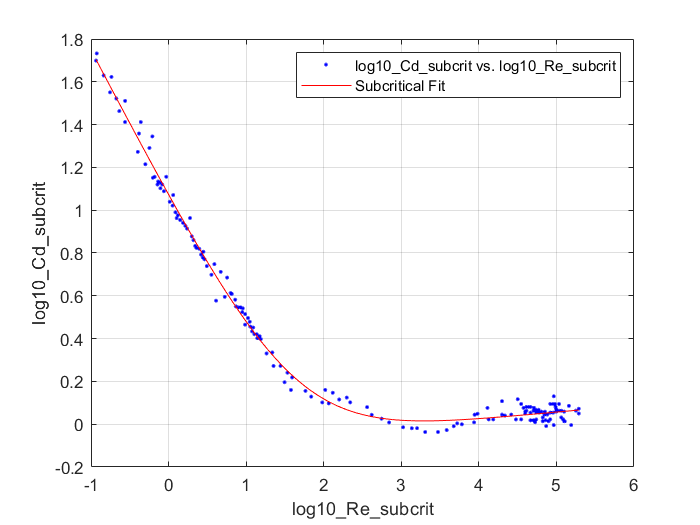

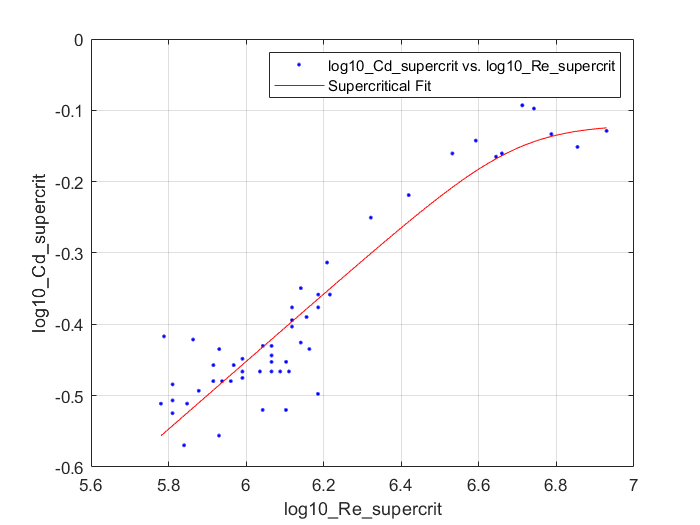

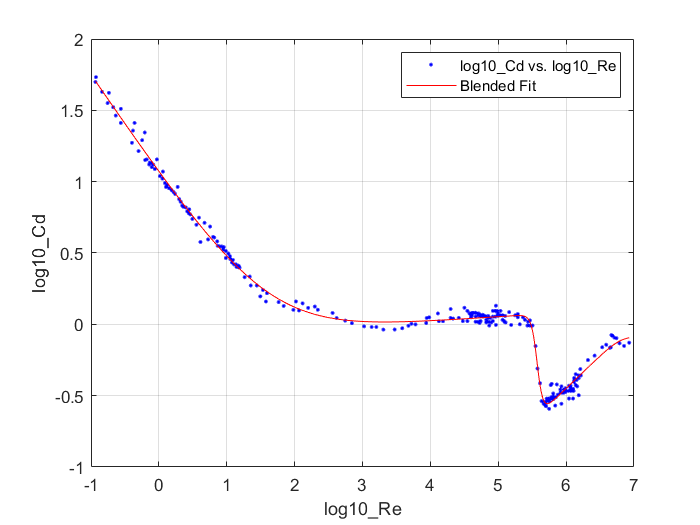

fits = 3×1 cell array
    {1×1 cfit}
    {1×1 cfit}
    {1×1 cfit}

figure
fits = createFits(log10_Re_subcrit, log10_Cd_subcrit, log10_Re_supercrit, log10_Cd_supercrit, log10_Re, log10_Cd)

fit = fits{3}

fit =      General model:
     fit(x) = (log10(10^(csub0*x+csub1)+csub2+csub3*x))*(1-1/(1+exp(-csigh*(x-
                    csigc))))  + (csup0+csupscl/csuph*log(exp(csuph*(csupc-
                    x))+1))*(1/(1+exp(-csigh*(x-csigc))))
     Coefficients (with 95% confidence bounds):
       csigc =       5.577  (5.565, 5.588)
       csigh =       23.75  (18.86, 28.63)
       csub0 =     -0.6989  (-0.7227, -0.6752)
       csub1 =       1.047  (1.033, 1.06)
       csub2 =      0.7044  (0.5648, 0.844)
       csub3 =     0.08465  (0.05414, 0.1152)
       csup0 =    -0.08236  (-0.1562, -0.008504)
       csupc =       6.802  (6.578, 7.026)
       csuph =          10  (fixed at bound)
       csupscl =     -0.4571  (-0.5102, -0.4039)

Make a shiny plot showing the fit:

figure
Res = logspace(-2, 8, 500)

Res = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


CDs_fit = 10.^fit(log10(Res))

CDs_fit =   278.7737
  269.9448
  261.3961
  253.1187
  245.1042
  237.3440
  229.8302
  222.5549
  215.5106
  208.6898


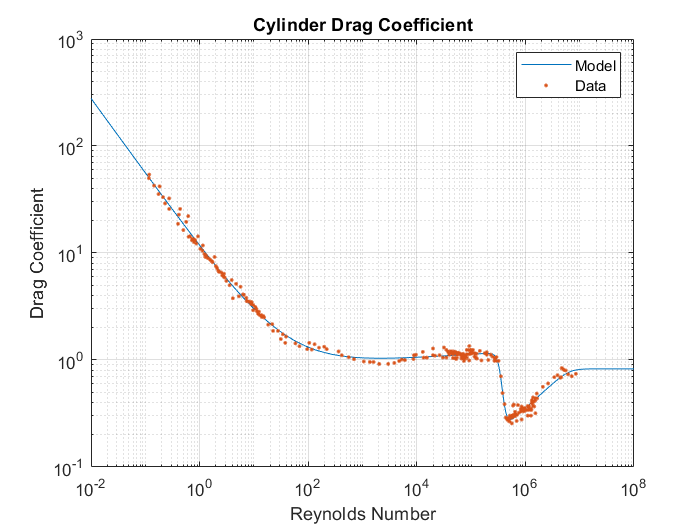

loglog(Res, CDs_fit)
hold on
scatter(10.^log10_Re, 10.^log10_Cd, ".")
legend("Model", "Data")
grid on
xlabel("Reynolds Number")
ylabel("Drag Coefficient")
title("Cylinder Drag Coefficient")
saveas(gcf, "cylinderdragfit.svg")

Extract the overall fit; convert it to Python code:

And display it for copy/pasting into Python:

names = coeffnames(fit)

names = 10×1 cell array
    {'csigc'  }
    {'csigh'  }
    {'csub0'  }
    {'csub1'  }
    {'csub2'  }
    {'csub3'  }
    {'csup0'  }
    {'csupc'  }
    {'csuph'  }
    {'csupscl'}

vals = coeffvalues(fit)

vals =     5.5767   23.7461   -0.6989    1.0465    0.7044    0.0847   -0.0824    6.8020   10.0000   -0.4571


for i=1:length(names)
    disp(sprintf("%s = %.16f", names{i}, vals(i)))
end

csigc = 5.5766722118597247
csigh = 23.7460859935990563
csub0 = -0.6989492360435040
csub1 = 1.0465189382830078
csub2 = 0.7044228755898569
csub3 = 0.0846501115443938
csup0 = -0.0823564417206403
csupc = 6.8020230357616764
csuph = 9.9999999999999787
csupscl = -0.4570690347113859


f=strrep(formula(fit),"^"," ** ");
disp(f)

(log10(10 ** (csub0*x+csub1)+csub2+csub3*x))*(1-1/(1+exp(-csigh*(x-csigc))))  + (csup0+csupscl/csuph*log(exp(csuph*(csupc-x))+1))*(1/(1+exp(-csigh*(x-csigc))))
